I_gray = imread("pout.tif");

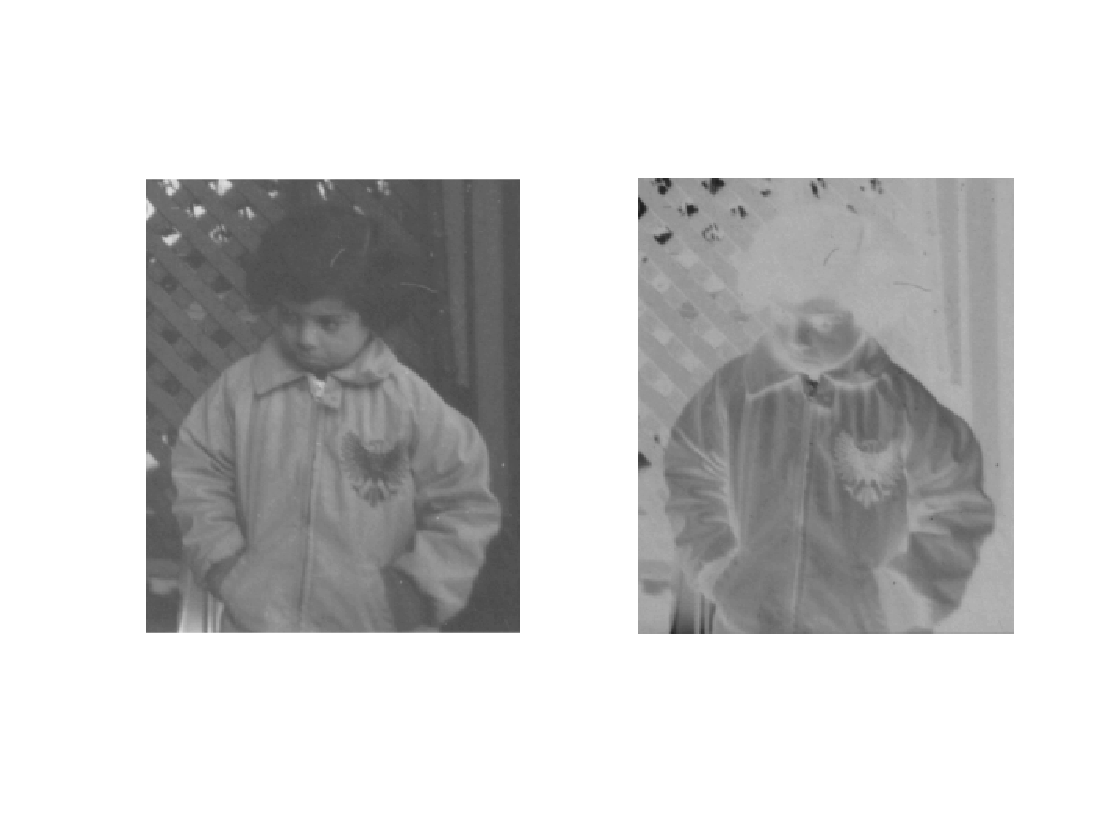

% 灰度反转
figure,subplot(1,2,1),imshow(I_gray);
subplot(1,2,2),imshow(255 - I_gray);

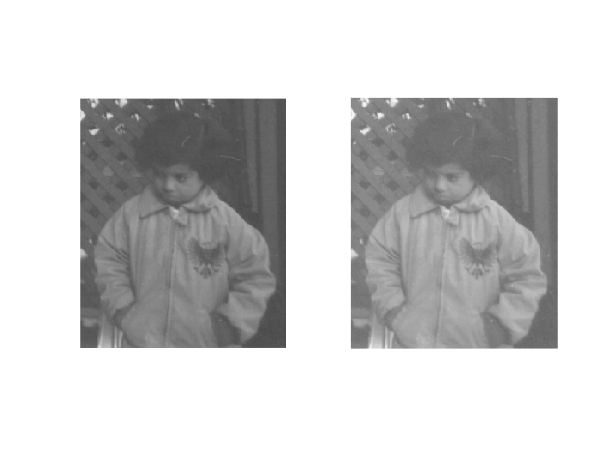

% 灰度对数变换
lambda = 3;
base =7;
figure,subplot(1,2,1),imshow(I_gray);
I_log = imLogAdjust(I_gray, lambda, base);
subplot(1,2,2),imshow(I_log);

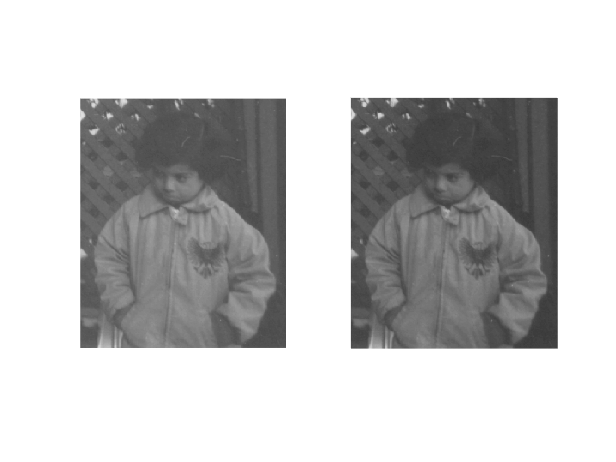

% 指数变换
lambda = 1;
power = 1.2;
figure,subplot(1,2,1),imshow(I_gray);
I_power = imPowerAdjust(I_gray, lambda, power);
subplot(1,2,2),imshow(I_power);

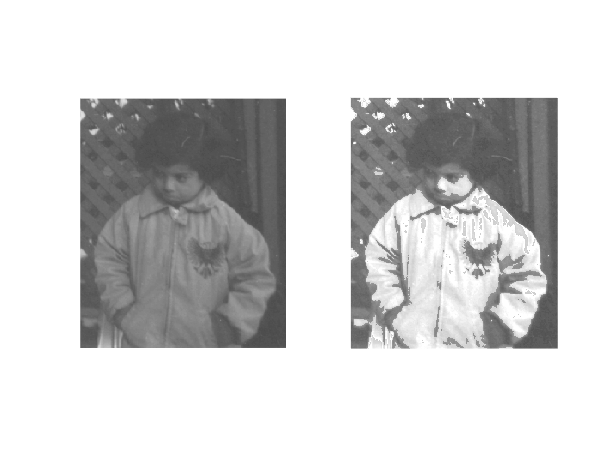

% 三段式线性变换
a = 0.1;
b = 0.6;
k1 = 0.1;
k2 = 1.6;
k3 = 1.2;
figure, subplot(1,2,1), imshow(I_gray);
I_linear = imLinearAdjust(I_gray, a, b, k1, k2, k3);
subplot(1,2,2), imshow(I_linear);

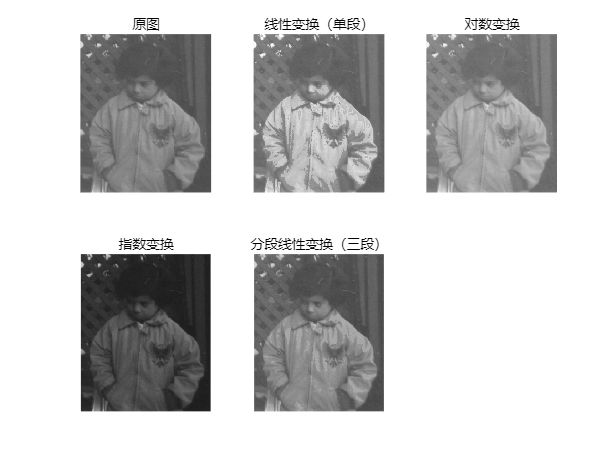

% 汇总
I_gray = imread("pout.tif");

% 线性变化
a1 = 0.2;
b1 = 0.6;
k = 1.2;
I_linear = imLinearAdjust(I_gray, a1, b1, k, k, k);

% 灰度对数变换
lambda = 3;
base =7;
I_log = imLogAdjust(I_gray, lambda, base);


% 指数变换
lambda = 1;
power = 1.8;
I_power = imPowerAdjust(I_gray, lambda, power);


% 三段式线性变换
a = 0.2;
b = 0.6;
k1 = 0.8;
k2 = 1.2;
k3 = 0.7;
I_linear_3 = imLinearAdjust(I_gray, a, b, k1, k2, k3);

figure,subplot(2,3,1),imshow(I_gray),title("原图");
subplot(2,3,2), imshow(I_linear),title("线性变换（单段）");
subplot(2,3,3),imshow(I_log),title("对数变换");
subplot(2,3,4),imshow(I_power), title("指数变换");
subplot(2,3,5), imshow(I_linear_3),title("分段线性变换（三段）");

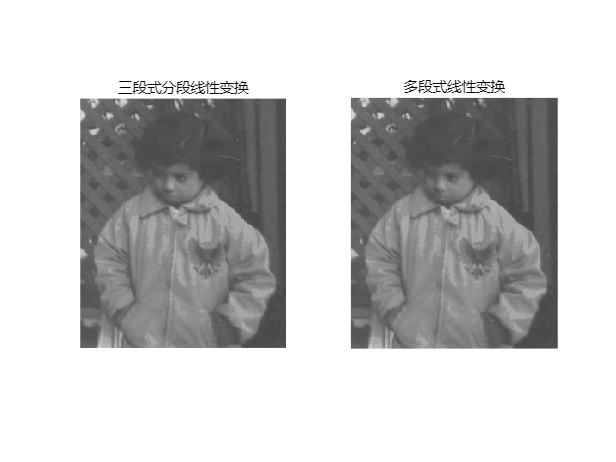

% 多段线性变换
I_linear_n = imLinearAdjust_n(I_gray, [0.2 0.6], [0.8 1.2 0.7]);

figure, subplot(1,2,1),imshow(I_linear_3),title("三段式分段线性变换");
subplot(1,2,2), imshow(I_linear_n), title("多段式线性变换");

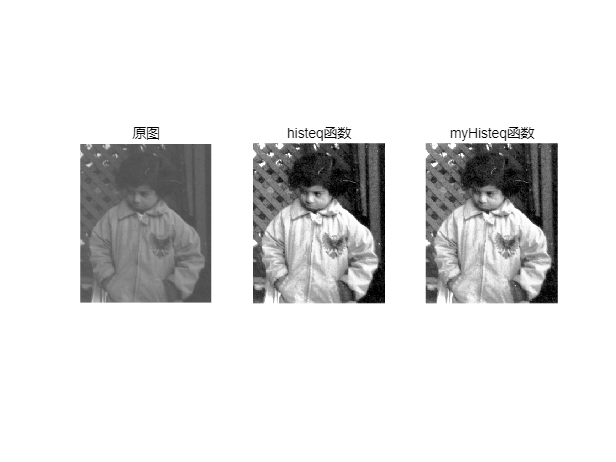

% 自定义直方均衡
% 直方图均衡化
I_histeq = histeq(I_gray);
[I_myHisteq map] = myHisteq(I_gray);
figure, subplot(1,3,1),  imshow(I_gray),title("原图");
subplot(1,3,2), imshow(I_histeq), title("histeq函数");
subplot(1,3,3), imshow(I_myHisteq), title("myHisteq函数");